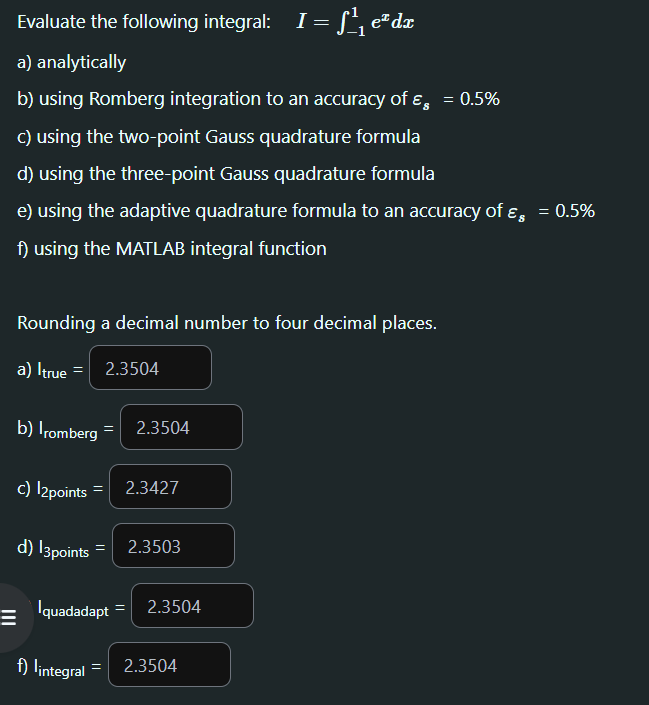

Function

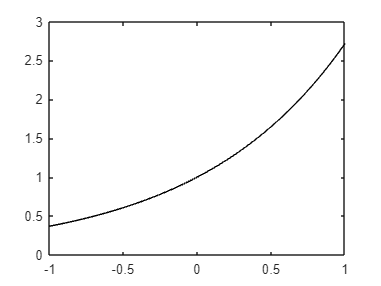

f=@(x) exp(x);

% xx = linspace(-1, 1);
% yy = f(xx);
% plot(xx,yy,'k-')

x = linspace(-1,1);
y = f(x);
plot(x,y,'k-')

To integrate function from 0 to 0.8

a = -1;
b = 1;
% 
% p = [exp(1)];
% q = polyint(p);
% 
% Itrue = diff(polyval(q, [a b]))

Iture = exp(1) - exp(-1)

Iture = 2.3504

Compute using composite trapezoidal rule

% ns = 200;
% 
% for k = 1:ns
%     I_trap(k) = trap(f,a,b,k);
%     err(k) = ( (Itrue - I_trap(k) ) / Itrue) * 100;
% end
% 
% [(1:ns)' I_trap' err']

Compute using Romberg integration

[I_romberg, ea, iter] = romberg(f,a,b)

I_romberg = 2.3504

ea = 1.7734e-08

iter = 4

Compute using Gauss-Legendre Formulas

a1 = (b+a)/2;
a2 = (b-a)/2;

% x = a1 + a2 * xd
% dx = a2 + dxd

% f2=@(xd) (400.*(a1 + a2 * xd).^5 - 900.*(a1 + a2 * xd).^4 + 675.*(a1 + a2 * xd).^3 - 200.*(a1 + a2 * xd).^2 + 25.*(a1 + a2 * xd) + 0.2)*a2;
f2=@(xd) exp(a1 + a2 * xd)*a2;

I_2_points = f2(-1/sqrt(3)) + f2(1/sqrt(3))

I_2_points = 2.3427

I_3_points = (5/9) * f2(-sqrt(3/5)) + ((8/9)*f2(0)) + (5/9)*f2(sqrt(3/5))

I_3_points = 2.3503

I_4_points = ((18 - sqrt(30))/36) * f2( (-sqrt( 525+70*sqrt(30) ))/35 ) + ((18 + sqrt(30))/36) * f2( (-sqrt( 525-70*sqrt(30) ))/35 ) + ((18 + sqrt(30))/36) * f2( (sqrt( 525-70*sqrt(30) ))/35 ) + ((18 - sqrt(30))/36) * f2( (sqrt( 525+70*sqrt(30) ))/35 )

I_4_points = 2.3504

Compute using adaptive quadrature

I_quadadapt = quadadapt(f,a,b)

I_quadadapt = 2.3504

Compute using Matlab's integral function

I_integral = integral(f,a,b)

I_integral = 2.3504